## How can you determine the response of a building to an earthquake?

During an earthquake, structures will oscillate in response to seismic waves traveling through the ground. In serious earthquakes, this can lead to structural damage or even collapse. 

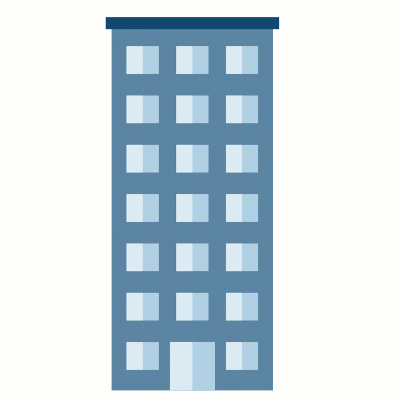

So how do you determine how a building will respond to the seismic waves? The answer lies in dynamic modeling.

In this script, you'll explore the double mass-spring-damper system and apply it to analyze a two-story building's response to simulated seismic waves.

# The Double Mass-Spring-Damper

clear % This clears the MATLAB workspace each time you run the script
addModelPaths % This helper adds the model paths

 Run this section to add the folder that contains the models to the MATLAB Search Path. This is necessary for the links to the models to work.

## 1. The double mass-spring-damper model

The double mass-spring-damper model couples two mass-spring-dampers into a single system. This system has two degrees of freedom (2-DOF): $x_1$ and $x_2$. In the system shown below, only one of the masses is connected to a rigid surface by a spring/damper pair.

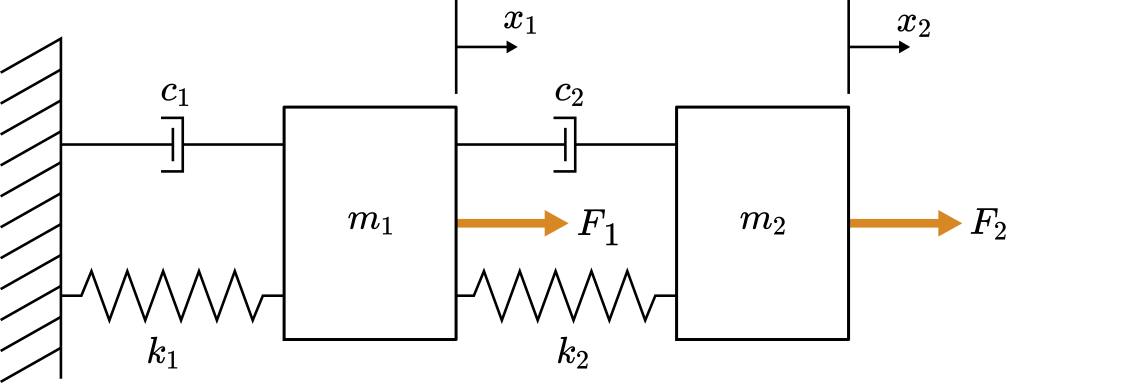

*Schematic of a double mass-spring-damper system.*

The parameters are the same as for a single mass-spring-damper, except now there are two of each:

- $k_1 ,k_2$: spring stiffness [N/m]

- $c_1 ,c_2$: damping [N$\cdot$s/m]

- $m_1 ,m_2$: mass [kg]

- $F_1 ,F_2$: externally applied force [N] (can be constant or time-dependent: $F(t)$)

The time-dependent behavior of the system is described using the variables: 

- $t$: time since the start of the simulation [s]

- $x_1 ,x_2$: time-dependent ($x_i=x_i(t)$) displacement of the mass from the reference equilibrium position [m]

Applying a force to either mass will induce vibrations. Energy will be transferred between the masses, and over time the vibrations will diminish as the dashpots reduce the energy of the system.

 ** Try**

- On paper, draw free body diagrams of the forces acting on each mass $m_1$ and $m_2$.

- Be careful when you assign the direction of the forces. Consider which direction the force of each spring will act based on the direction that $x_i$ points. A compressed spring will produce an outward force, while an extended spring will produce an inward force.

- After drawing the free body diagram, apply Newton's second law to derive the equations of motion:      

                $m_1\ddot{x}_1 \;=\;\;\sum Forces$   and   $m_2\ddot{x}_2 \;=\;\;\sum Forces$.

showSolutionFBD = false; % Click the checkbox to view the solution
if(showSolutionFBD)
    clf
    I = imread("images/doubleMSDFreeBodyDiagram.png");
    imshow(I);
end

## 2. Work with the ODE system in MATLAB

The double mass-spring-damper differential equations that you derived in the previous section are:

    
$$m_1 \ddot{x}_1 = F_1 + k_2(x_2 - x_1) + c_2 (\dot{x}_2 - \dot{x}_1) - k_1 x_1 - c_1 \dot{x}_1$$


    
$$m_2 \ddot{x}_2 = F_2 - k_2(x_2 - x_1) - c_2 (\dot{x}_2 - \dot{x}_1)$$


To solve this system in Simulink, you can create a MATLAB Function block that evaluates these expressions. You can use MATLAB commands to perform symbolic computations and then automatically generate a MATLAB Function block from the result.

** Exercise. **In this exercise, you will create symbolic expressions for the double mass-spring-damper ODEs and create a MATLAB Function block in Simulink that evaluates them.

**Task 1. **Write the double mass-spring-damper equations in terms of the pre-defined symbolic variables and assign them to `msdEq1` and `msdEq2`.

  **Pro-tip**: When you write a symbolic equation, you assign the whole equation to a MATLAB variable using $=$. This means that the equals sign in the symbolic equation must be written using `==`. For example: 

syms x_1 x_2 x_dot_1 x_dot_2 x_ddot_1 x_ddot_2 m_1 m_2 k_1 k_2 c_1 c_2 F_1 F_2 % Symbolic variables for you to use
msdEq1 = NaN % Replace NaN with the first equation
msdEq2 = NaN % Replace NaN with the second equation
checkMSDeq(msdEq1,msdEq2) % This helper function (located at the bottom of the script) checks your equation

**Task 2. **Solve for `x_ddot_1 `in the first equation and` x_ddot_2` in the second using [`solve(equation,variable)`](https://www.mathworks.com/help/symbolic/solve.html) and assign the results to `expr1` and `expr2`. In this syntax, `equation` is the symbolic equation to be solved and `variable` is the symbolic variable to be solved for.

expr1 = NaN % Replace NaN with a call to solve
expr2 = NaN % Replace NaN with a call to solve
checkExpressions(expr1,expr2) % This helper function (located at the bottom of the script) checks your expressions

**Task 3. **Open the Simulink model [mfbDouble.slx](matlab: open_system('models/mfbDouble')).

**Task 4. **With your symbolic computations complete, you can add the expressions to a MATLAB Function block in Simulink.

One way to do this is to copy and paste the expressions into a MATLAB Function block in Simulink. Another way is to use the [`matlabFunctionBlock`](https://www.mathworks.com/help/symbolic/matlabfunctionblock.html) command in MATLAB to generate the block from the symbolic expressions automatically.

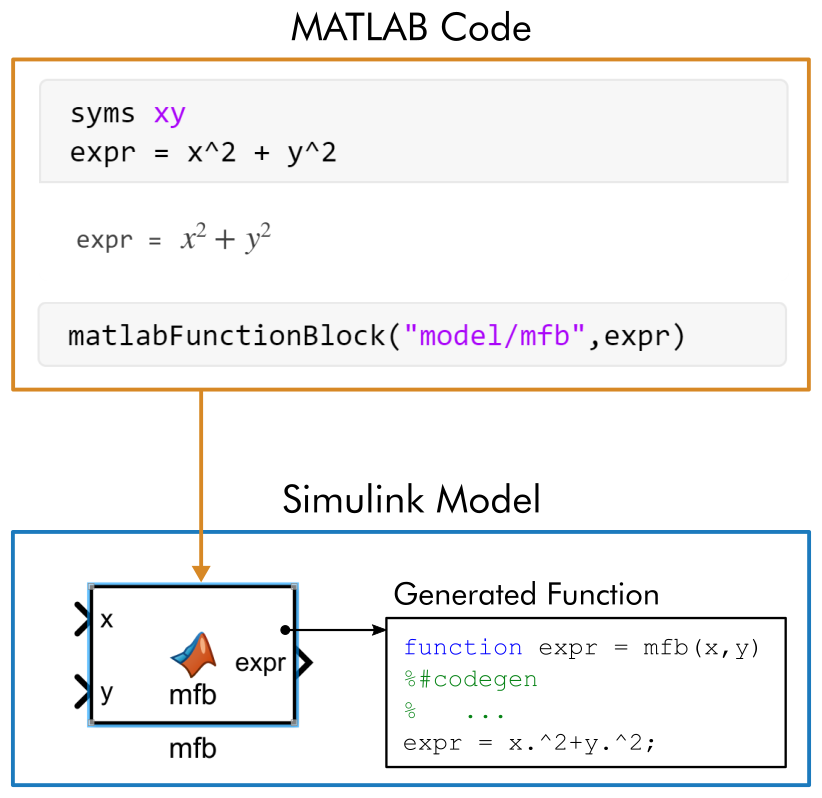

*Example of using the matlabFunctionBlock command to generate a MATLAB Function block from a symbolic expression*

In the space provided below, write a call to `matlabFunctionBlock` with the syntax:

In this syntax, set:

- `modelName` to the name of the model: `mfbDouble` (do not include the extension: .slx)

- `blockName` to the name you want to give the block, e.g., `double msd`

- `f1` to `expr1`, the symbolic expression for $\ddot{x}_1$, and similarly for `f2`

- the output names to `x_ddot_1` and `x_ddot_2`

- the `"Optimize" flag` to `false`

Note that the model must be open for the `matlabFunctionBlock` function to work.

% Write a call to matlabFunctionBlock here


**Task 5. **With the MATLAB Function block created, you can test if it accurately evaluates the expressions.

- Expand the size of the MATLAB Function block

- Connect the inputs to the constants and the outputs to the "check output" subsystem

- Run the model and observe the Display block

## 3. Solve the double mass-spring-damper model in Simulink

You can solve the coupled ODE system in Simulink using the same components required to solve the single mass-spring-damper ODE: a MATLAB Function block to define the equations and integrator blocks to integrate in time.

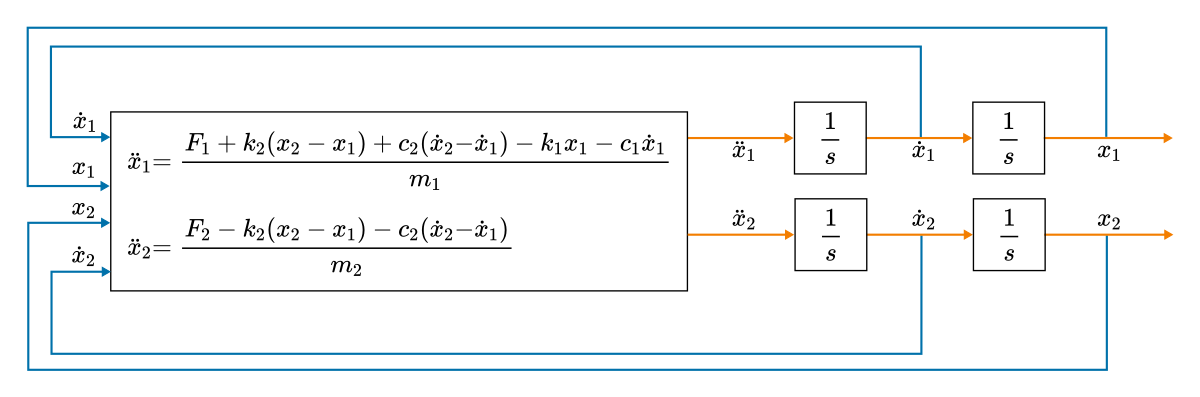

*This 2-DOF system requires twice as many integrator blocks as the single mass-spring-damper system.*

** Exercise. **In this exercise, you will construct a Simulink model that solves the double mass-spring-damper.

- Open [msdDouble.slx](matlab: open_system('models/msdDouble')).

- Add four **Integrator **blocks and connect them to solve the ODE, as illustrated in the block diagram above.

- Add eight **Constant **blocks to provide the first eight inputs to the MATLAB Function block. Set the constants to 

- $k_1 = 20$ N/m and $k_2 = 5$ N/m.

- $c_1 = 0.25$ N$\cdot$s/m and $c_2 = 0.5$ N$\cdot$s/m

- $m_1$ = 2 kg and $m_2 = 0.5$ kg

- $F_1 = F_2 = 0$ N

- Set the initial conditions in the Integrator blocks to $\dot{x}_1(0) = 0$, $\dot{x_2}(0) = 8$, $x_1(0)=0$, and $x_2(0)=0$.

- Add a Scope block and connect it to the $x_1$ and $x_2$ signals.

- Run the model. If correct, you should see the output shown below.

Having trouble? Check out the completed model: [msdDoubleSoln.slx](matlab: open_system('models/msdDoubleSoln')).

            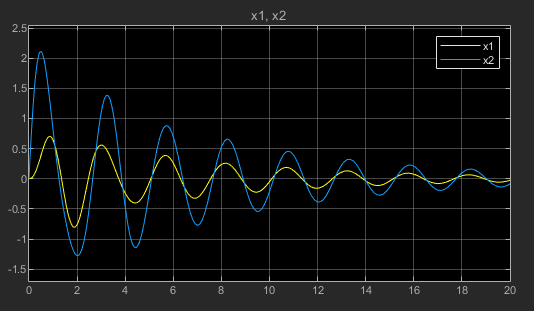

*           Solution to the double mass-spring-damper system*

**Visualize the motion of the double mass-spring-damper**

With the model complete, you can visualize the motion. `msdDoubleSimulationOutput.slx`. 

n = 150; % The number of steps used in the visualization
visualize = false; % Click the checkbox to show the visualization
if(visualize)
    simOut = sim("models/msdDoubleSimulationOutput"); % simulates a completed double mass-spring-damper model
    animateMSD(simOut.tout,simOut.yout,0.75,n) % helper function that creates an animation of the output from the model
end

 ** Try**

Open the Simulink model [msdDoubleSimulationOutput.slx](matlab: open_system("models/msdDoubleSimulationOutput")) and 

- Increase the stiffness of the second spring. Then, rerun this section of the script. How is the behavior affected?

- Try adjusting the initial conditions and parameters. Can you find parameters that make the masses oscillate out of phase?

## 4. Modeling building vibrations using the double mass-spring-damper

Earthquakes generate several types of seismic waves that propagate both through the earth and along its surface. *Love waves* decay slowly and so are particularly destructive outside the epicenter of the earthquake.

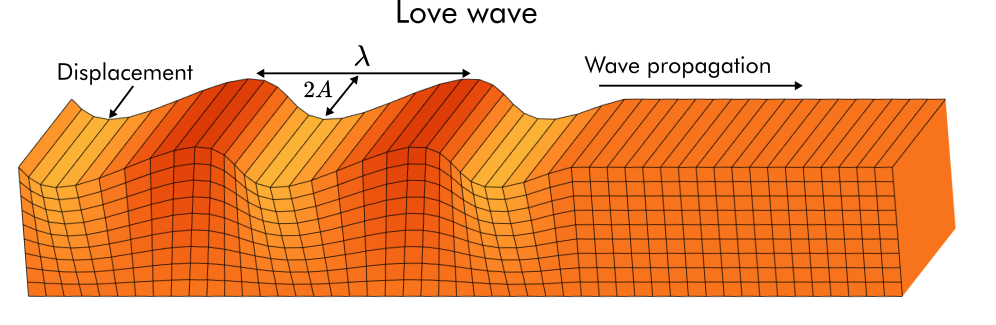

*Love waves cause horizontal displacements at the Earth's surface. Below the surface, their magnitude decays rapidly.*

In this exercise, you will analyze the horizontal motion of a two-story building under the effects of seismic waves. To reduce complexity, simplifying assumptions are made:

- The walls are assumed to be flexible and massless. 

- The floors are assumed to be rigid masses connected by spring-dampers (the walls). 

- Only horizontal motion is modeled.

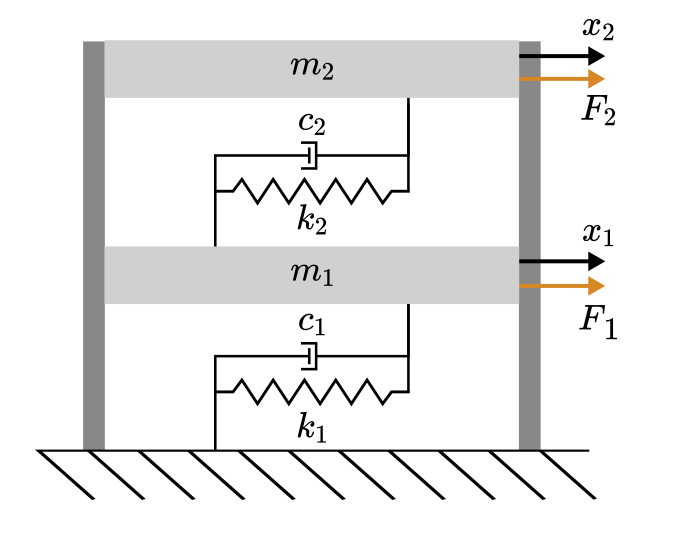

*Simple 2-DOF mass-spring-damper idealization of the horizontal motion of a two-story building.*

The building model is assumed to have the following characteristics:

- Effective masses: $m_1 =30,000\;\left\lbrack \textrm{kg}\right\rbrack$ and $m_2 =13,500\;\left\lbrack \textrm{kg}\right\rbrack$

- $k_1 =\;11\times {10}^6 \left\lbrack \frac{\mathrm{N}}{\mathrm{m}}\right\rbrack$, $k_2 =5\times {10}^6 \left\lbrack \frac{\mathrm{N}}{\mathrm{m}}\right\rbrack$

- $c_1 =\;2625\;\left\lbrack \frac{\mathrm{N}\cdot \;\mathrm{s}}{\mathrm{m}}\right\rbrack$, $c_2 =\;2475\;\left\lbrack \frac{\mathrm{N}\cdot \;\mathrm{s}}{\mathrm{m}}\right\rbrack$

The seismic waves are simulated by applying periodic forcing to the first mass:

- $F_1 \left(t\right)=F_0 \;\sin \left(\frac{2\pi t}{T}\right)\;\;$ while $t_s < t < t_f$, and 0 otherwise. The duration $[t_s,t_f]$, period $T$, and forcing amplitude $F_0$, are set later.

- 
$$F_2 = 0$$


** Exercise**. In this exercise, you will analyze the double mass-spring-damper building model's natural vibrations and response to a periodic forcing.

**Part 1. **Structures have a natural oscillation period that is determined by their structure. In this part, you will measure the period of the natural oscillation of the mass-spring-damper building model.

- Open [msdDoubleBuilding.slx](matlab: open_system('models/msdDoubleBuilding')).

- Set the initial conditions of the model to $x_1(0) = 0.1$, $x_2(0) = 0$, $\dot{x}_1(0) = 0$, and $\dot{x}_2(0) = 0$ by double-clicking the [mask image](matlab: hilite_system('msdDoubleBuilding/double mass-spring-damper'); pause(1); hilite_system('msdDoubleBuilding/double mass-spring-damper','none');). 

- Ensure that no force is applied (set [F0](matlab: hilite_system('msdDoubleBuilding/F0 [N]'); pause(1); hilite_system('msdDoubleBuilding/F0 [N]','none');) to zero), and the remainder of the parameters are set to the values listed above.

- Set the simulation stop time to 5 s. 

- Run the simulation. 

- View the [scope](matlab: hilite_system('msdDoubleBuilding/Scope msd'); pause(1); hilite_system('msdDoubleBuilding/Scope msd','none');). You should notice that multiple oscillation frequencies are present but that the second mass oscillates at a (mostly) regular frequency. Measure the period of the oscillation by measuring the time elapsed between the first two absolute minima of $x_2$.

 **Pro-tip**: You can rescale the vertical axis using the rescale tool  .

x2_period = [ ]; % [s] Record the period that you measured here
checkPart1(x2_period)

**Part 2. **In this part, you will subject the double mass-spring-damper system to a low-frequency forcing.

- Simulate a Love wave by setting the forcing parameters to $F_0 = 7500$ N, $T = 25$ s, $t_s = 10$, and $t_f = 110$. 

- Set the simulation stop time to 150 s.

- Set the initial conditions of the model to zero ($x_1(0) = 0$, $x_2(0) = 0$, $\dot{x}_1(0) = 0$, and $\dot{x}_2(0) = 0$).

- Simulate the model. If your parameters are set correctly, you should see the graph below in the scope (you might need to rescale the axes:   ).

                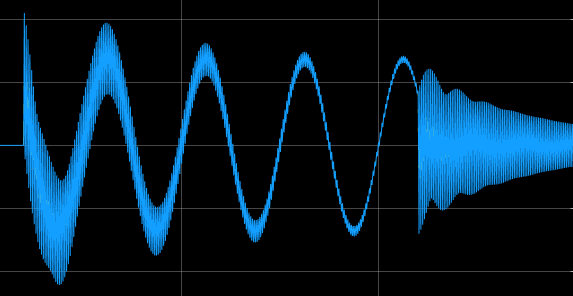

        5. Estimate the minimum value of $x_2$ from the scope and type the answer below (in meters). Note that the axes may be scaled by a multiplier (e.g. $\times 10^{-1}$).

x2_disp = [ ];% [m] Record the minimum value of x_2
checkPart2(x2_disp)

 **Reflect:**

- The signal has two scales: a rapid oscillation and a much slower oscillation. What causes each of these?

- The low frequency forcing leads to about a 6mm displacement. If the seismic wave had a different period, this might change. What period forcing do you think would lead to larger displacements?

**Part 3. **If the frequency of the forcing is close to the natural oscillation frequency of the structure, known as the *resonant frequency*, consecutive oscillations stack. 

- Other seismic waves have a higher frequency. Keep the other parameters the same but set the period to $T = 0.46$ and observe the result. Estimate the maximum displacement achieved by $x_2$ and type your answer in the space below (in meters).

x2_max = [ ];% m
checkPart3(x2_max)

 **Reflect:**

- Set the period to T = 1.2 and rerun the simulation. Observe that even this small change to the period reduces the resonance of the oscillations.

- If the walls were to become stiffer (increasing the stiffness parameters, $k_i$), would the resonant period be lower or higher? Double the stiffnesses and rerun the simulation to test your theory.

- What other methods could you use to solve for the resonant frequencies of the mass-spring-damper system?

### 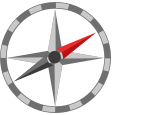**Further exploration**

You can use Simscape to solve mass-spring-damper systems without deriving or integrating differential equations. In this alternative approach, you use abstract mechanical system components to define the system, rather than defining the ODE. To learn more about this approach, visit the Simscape documentation.

- [Mass-Spring-Damper in Simulink and Simscape](https://www.mathworks.com/help/physmod/simscape/ug/mass-spring-damper-in-simulink-and-simscape.html) 

- [Double Mass-Spring-Damper in Simulink and Simscape](https://www.mathworks.com/help/physmod/simscape/ug/double-mass-spring-damper-in-simulink-and-simscape.html)

**Helper functions**

These functions check answers and generate animations.

function correct = isEqualCheck(userSubmission,correctAnswer)
    correct = isEqualCheckCustom(userSubmission,correctAnswer,"Correct!","Your answer does not match the expected result.");
end

function correct = isEqualCheckCustom(userSubmission,correctAnswer,correctResponse,incorrectResponse)
    correct = true;
    if( isequal(userSubmission,correctAnswer) )
        disp(correctResponse)
    else
        warning(incorrectResponse)
        correct = false;
    end
end

function checkMSDeq(msdEq1User,msdEq2User)
    syms x_1 x_2 x_dot_1 x_dot_2 x_ddot_1 x_ddot_2 m_1 m_2 k_1 k_2 c_1 c_2 F_1 F_2
    msdEq1 = m_1*x_ddot_1 == F_1 + k_2*(x_2 - x_1) + c_2*(x_dot_2 - x_dot_1) - k_1*x_1 - c_1*x_dot_1; 
    msdEq2 = m_2*x_ddot_2 == F_2 - k_2*(x_2 - x_1) - c_2*(x_dot_2 - x_dot_1); 

    isEqualCheckCustom(solve(msdEq1User,x_ddot_1),solve(msdEq1,x_ddot_1),"First equation correct!","First equation not correct");
    isEqualCheckCustom(solve(msdEq2User,x_ddot_2),solve(msdEq2,x_ddot_2),"Second equation correct!","Second equation not correct");
end

function checkExpressions(expr1User,expr2User)
    syms x_1 x_2 x_dot_1 x_dot_2 x_ddot_1 x_ddot_2 m_1 m_2 k_1 k_2 k_3 c_1 c_2 c_3 F_1 F_2
    msdEq1 = m_1*x_ddot_1 == F_1 + k_2*(x_2 - x_1) + c_2*(x_dot_2 - x_dot_1) - k_1*x_1 - c_1*x_dot_1; 
    msdEq2 = m_2*x_ddot_2 == F_2 - k_2*(x_2 - x_1) - c_2*(x_dot_2 - x_dot_1);

    isEqualCheckCustom(expr1User,solve(msdEq1,x_ddot_1),"First expression correct!","First expression not correct");
    isEqualCheckCustom(expr2User,solve(msdEq2,x_ddot_2),"Second expression correct!","Second expression not correct");
end

function animateMSD(tin,xin,spacingMultiplier,steps) 
    
    Nmass = size(xin,2); % Number of masses

    % Options that determine how the graph will look
    colors = lines(Nmass); 
    w = 1; % Mass width
    h = 2; % Height of masses
    y = 0; % Vertical position
     
    % Local variables
    t = linspace(tin(1),tin(end),steps);
    x = zeros(steps,Nmass);
    for k = 1:Nmass
        x(:,k) = interp1(tin,xin(:,k),t);
    end
    spacing = 2*max(abs(x),[],"all")*spacingMultiplier;
    xmax = spacing*2.5 + 2;
    
    % Loop to create the animation
    figure;    
    for j = 1:numel(t)
       
        subplot(2,1,1) % This shows the masses
        cla
        hold on
        x0k = 0;
        for k = 1:Nmass
            % Plot springs
            xc = spacing*k+x(j,k)-w/2;       
            xs = linspace(x0k,xc,12);
            ys = 0.25*(-1).^(1:numel(xs));
            plot(xs,ys + 0.5,"k");
            % Plot dampers
            yd = 1.65;
            xd = x0k + (xc-x0k)*0.5+0.1;
            xd2 = x0k + (xc-x0k)*0.5;
            xd3 = x0k + (xc-x0k)*0.5 + 0.2;
            plot([x0k,xd,NaN,xd,xd],[yd,yd,NaN,yd-0.1,yd+0.1],"k")
            plot([xd2,xd3,NaN,xd2,xd3,NaN,xd3,xd3,NaN,xd3,xc],[yd-0.15,yd-0.15,NaN,yd+0.15,yd+0.15,NaN,yd-0.15,yd+0.15,NaN,yd,yd],"k")
            % Update position
            x0k = xc + w;
            % Plot masses
            x1 = spacing*k + x(j,k) - 0.5;
            rectangle("Position",[x1 y w h],"FaceColor",colors(k,:))
            text(x1 + w/2, h/2,"m_" + num2str(k),"HorizontalAlignment","center","color","w")
            % Plot x1, x2 distances
            quiver(spacing*k, y+h*1.1, x(j,k),0,"k-","MaxHeadSize",1/(x(j,k))^2)
            plot([1;1]*[spacing*k, spacing*k+x(j,k)],[0.95;1.05]*(y*[1,1]+h*1.1),"k-","markersize",12)
            text((spacing*k + spacing*k+x(j,k) )/2,(y+h*1.3),"x_"+num2str(k),"HorizontalAlignment","Center")
        end
        hold off
        axis([0,xmax,-1,3])
        set(gca,"ytick",[])
        xlabel("reference axis [m]")
    
        subplot(2,1,2) % This shows the position plots with moving markers
        cla
        hold on
        plot(t,x)
        for k = 1:Nmass
            plot(t(j),x(j,k),"ko","MarkerFaceColor",colors(k,:))
        end 
        xlabel("t [s]")
        ylabel("x [m]")
        hold off
        box off
        drawnow
    end
end

function checkPart1(x2_period)
    if(abs(x2_period - 0.463) < 0.1)
        disp("Close enough!")
    else
        warning("Not close enough.") 
    end
end

function checkPart2(x2_disp)
    if(abs(x2_disp - (-0.0011)) < 0.001 )
        disp("Close enough!")
    else
        warning("Not close enough.") 
    end
end

function checkPart3(x2_max)
    if(abs(x2_max - 0.068) < 0.01 )
        disp("Close enough!")
    else
        warning("Not close enough.") 
    end
end

function addModelPaths()
    % Adds the paths for the models and images
    scriptPath = fileparts(matlab.desktop.editor.getActiveFilename);
    addpath(scriptPath,scriptPath + "/images/",scriptPath + "/models/")
end

% Suppress unused suggestions
%#ok<*UNRCH> 
%#ok<*DEFNU> 